### Problem 3

In this problem you want to make a plot of the $log_{10} T-log_{10}\rho$ plane showing which form of pressure (ideal gas, degeneracy, or radiation) dominates in each region. Consider density to range from $10^{-4}\text{ g cm}^{-3}<\rho<10^{10}\text{ g cm}^{-3}$ and temperature to range from $10\text{ K }<T<10^{10}\text{ K}$. We can estimate the boundaries between the different pressure regimes by setting the pressures equal. For instance, the boundary between ideal gas and radiation is given by: 


$$\frac{\rho kT}{\mu m_u}\sim\frac13aT^4$$


You can choose values of $\mu$ and $\mu_e$ appropriate for the Sun. Draw the following on your plot: 

(a) the boundary between ideal gas and radiation 

(b) the boundary between ideal gas and electron degeneracy 

(c) the boundary non-relativistic and relativistic electron degeneracy 

(d) draw a point indicate approximately the central conditions of the Sun are

# Solution

### (a) the boundary between ideal gas and radiation 

The boundary between ideal gas and radiation is defined by $P_\text{gas}=P_\text{rad}$:

syms P_rad P_gas P_e P_e_r rho a T k_B mu m_H K_1 K_2 mu_e positive
digits(5)
P_rad=a*T^4/3;
P_gas=rho*k_B*T/mu/m_H;
disp(P_gas==P_rad)

$$\frac{T\,k_{B}\,\rho }{m_{H}\,\mu }=\frac{T^{4}\,a}{3}$$

Express $T$ as a function of $\rho$

T1=solve(P_gas==P_rad,T)

$$T1 = {\left(\frac{3\,k_{B}\,\rho }{a\,m_{H}\,\mu }\right)}^{1/3}$$

Put in values (in SI units)

T1=simplify(subs(T1,[k_B a m_H rho],[const.k_B 8*pi^5*const.k_B^4/const.c^3/15/const.h^3 const.m_H symunit().kg/symunit().m^3*rho]))

$$T1 = \frac{3.2065e+6\,\rho^{1/3}}{\mu^{1/3}}\,K$$

#### (b) the boundary between ideal gas and degenarate electron

The boundary between ideal gas and (non-relativistic)  degenerate electron is defined by $P_\text{gas}=P_\text{e}$

P_e=K_1*(rho/mu_e)^(5/3);
disp(P_gas==P_e)

$$\frac{T\,k_{B}\,\rho }{m_{H}\,\mu }=K_{1}\,{\left(\frac{\rho }{\mu_{e}}\right)}^{5/3}$$

Express $T$ as a function of $\rho$

T2=simplify(solve(P_gas==P_e,T))

$$T2 = \frac{K_{1}\,m_{H}\,\mu \,\rho^{2/3}}{k_{B}\,{\mu_{e}}^{5/3}}$$

Put in values (in SI units)

T2=simplify(subs(T2,[k_B K_1 m_H rho],[const.k_B 1e7*symunit().m^4*symunit().kg^(-2/3)/symunit().s^2 const.m_H symunit().kg/symunit().m^3*rho]))

$$T2 = \frac{1202.7\,\mu \,\rho^{2/3}}{{\mu_{e}}^{5/3}}\,K$$

Similarly, we can find the boundary between ideal gas and relativistic degenerate electron as

P_e_r=K_2*(rho/mu_e)^(4/3);
T3=simplify(solve(P_gas==P_e_r,T));
T3=simplify(subs(T3,[k_B K_2 m_H rho],[const.k_B 1.24e10*symunit().m^3*symunit().kg^(-1/3)/symunit().s^2 const.m_H symunit().kg/symunit().m^3*rho]))

$$T3 = \frac{1.4914e+6\,\mu \,\rho^{1/3}}{{\mu_{e}}^{4/3}}\,K$$

#### (c) the boundary non-relativistic and relativistic degenararte electron

The boundary non-relativistic and relativistic electron degeneracy is given by $P_\text{e}=P_\text{e,r}$

disp(P_e==P_e_r)

$$K_{1}\,{\left(\frac{\rho }{\mu_{e}}\right)}^{5/3}=K_{2}\,{\left(\frac{\rho }{\mu_{e}}\right)}^{4/3}$$

Plug in numbers and solve for $\rho$:

rho1=solve(P_e==P_e_r,rho)

$$rho1 = \frac{{K_{2}}^{3}\,\mu_{e}}{{K_{1}}^{3}}$$

rho1=vpa(subs(rho1,[K_1 K_2],[1e7*symunit().m^4*symunit().kg^(-2/3)/symunit().s^2 1.24e10*symunit().m^3*symunit().kg^(-1/3)/symunit().s^2]))

$$rho1 = 1.9066e+9\,\mu_{e}\,\frac{\mathrm{kg}}{m^{3}}$$

#### (d) Plot the diagram and draw the point indicates Sun

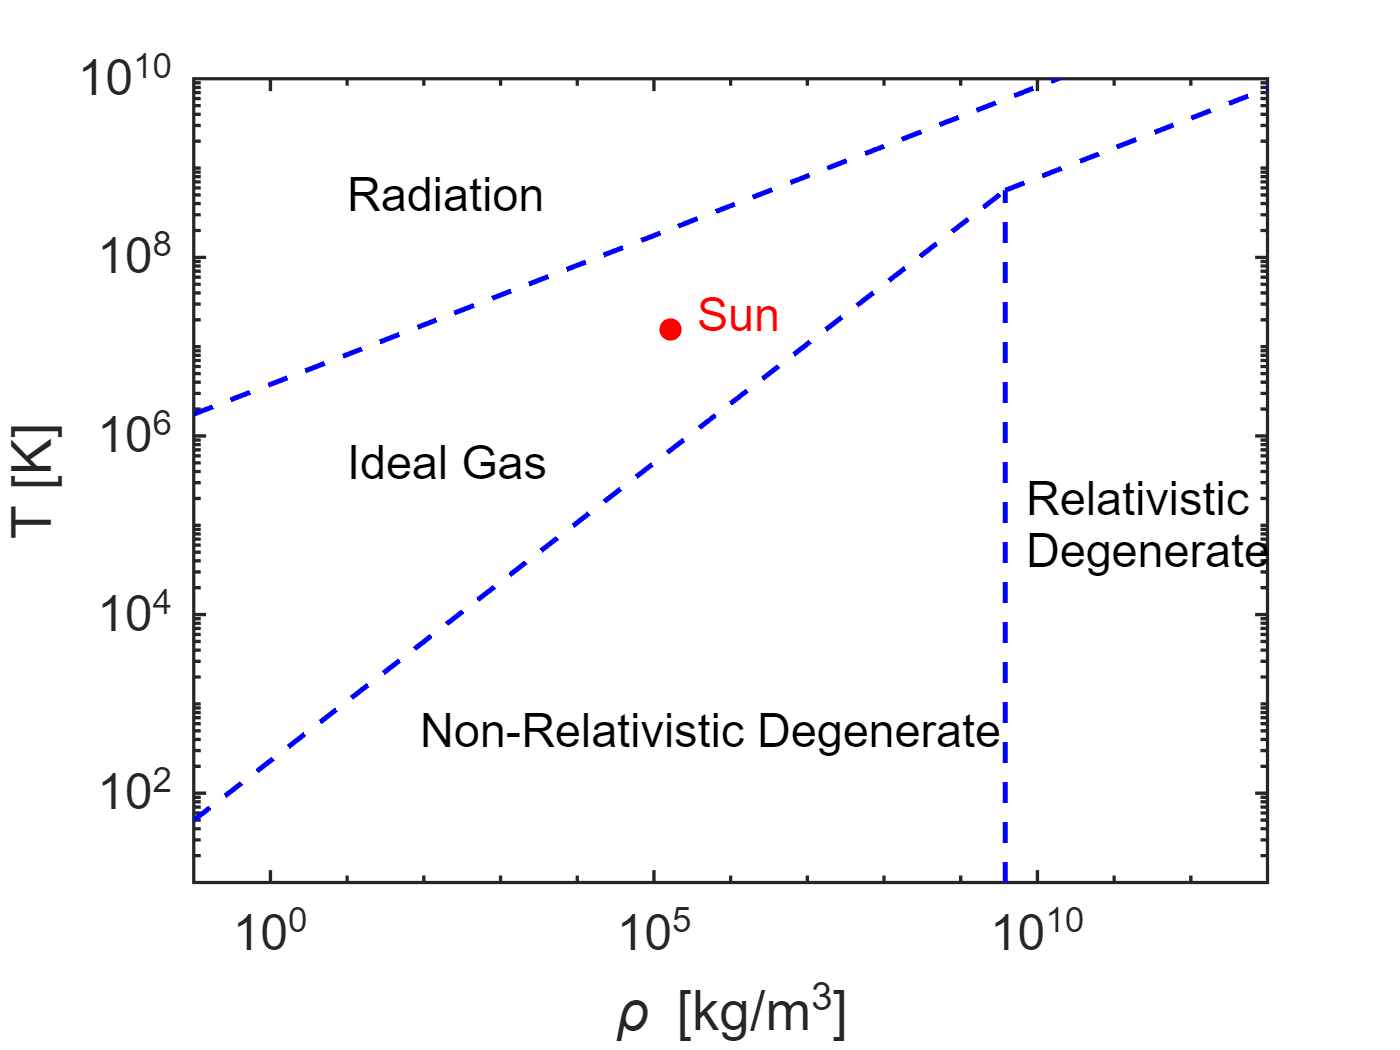

%Take mu = 0.61 and mu_e = 2.
T1=separateUnits(subs(T1,[mu mu_e],[0.61 2]));
T2=separateUnits(subs(T2,[mu mu_e],[0.61 2]));
T3=separateUnits(subs(T3,[mu mu_e],[0.61 2]));
rho1=double(separateUnits(subs(rho1,[mu mu_e],[0.61 2])));
%Plot the boundary between ideal gas and radiation
fplot(T1,"LineWidth",1.5,"LineStyle","--","Color","b")
hold on
%Plot the boundary between ideal gas and non-relativistic degenerate electron
fplot(T2,[0.1 rho1],"LineWidth",1.5,"LineStyle","--","Color","b")
%Plot the boundary between ideal gas and relativistic degenerate electron
fplot(T3,[rho1 1e13],"LineWidth",1.5,"LineStyle","--","Color","b")
%Plot the boundary between non-relativistic degenerate and relativistic degenerate
plot([rho1 rho1],[10 subs(T2,rho,rho1)],"LineWidth",1.5,"LineStyle","--","Color","b")
%Plot the position of the Sun. The Sun's data is from Nasa
plot(1.622e5,1.571e7,".","MarkerSize",20,"Color","r")
%Set logarithmic scale and axis range
set(gca(),'XScale','log','YScale','log')
xlim([0.1 1e13]);ylim([10 1e10]);
set(gca(),"FontSize",15,"LineWidth",1)
%Set lable
xlabel("\rho [kg/m^3]");ylabel("T [K]");
%Set Text
text(1.622e5+2e5,1.571e7+7e6,"Sun","FontSize",14,"Color","r")
text(9e1,5e2,"Non-Relativistic Degenerate","FontSize",14,"Color","k")
text(7e9,1e5,["Relativistic" "Degenerate"],"FontSize",14,"Color","k")
text(1e1,5e5,"Ideal Gas","FontSize",14,"Color","k")
text(1e1,5e8,"Radiation","FontSize",14,"Color","k")

This shows the Sun's model is well within the ideal-gas region of the equation of state.